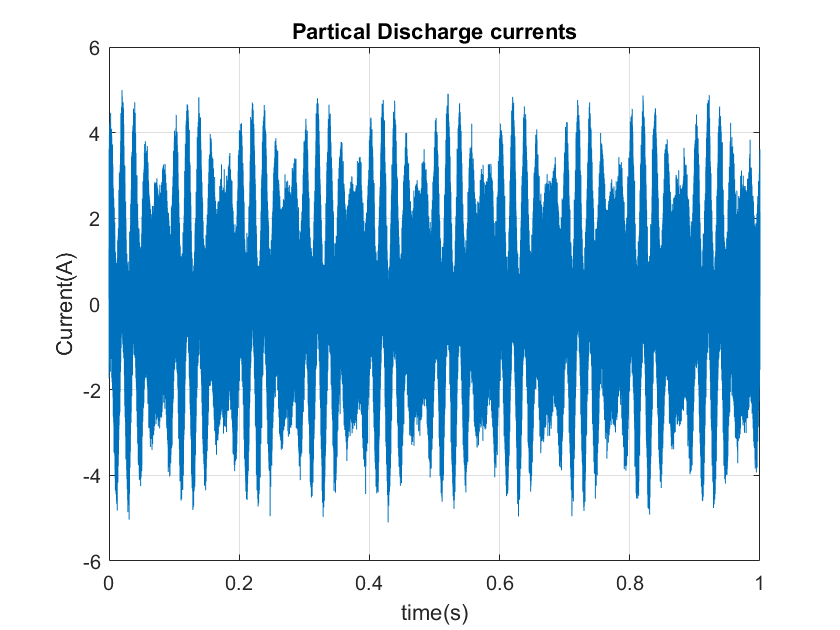

rng default
Fs = 20000000;
t = 0:1/Fs:1-1/Fs;
%x = cos(2*pi*80000*t) + randn(size(t));
x = sin(2*pi*60*t)+sin(2*pi*1000000*t)+0.5*randn(size(t))+sin(2*pi*50000000*t)+cos(2*pi*50*t);

plot(t,x)
grid on
title('Partical Discharge currents')
xlabel('time(s)')
ylabel('Current(A)')

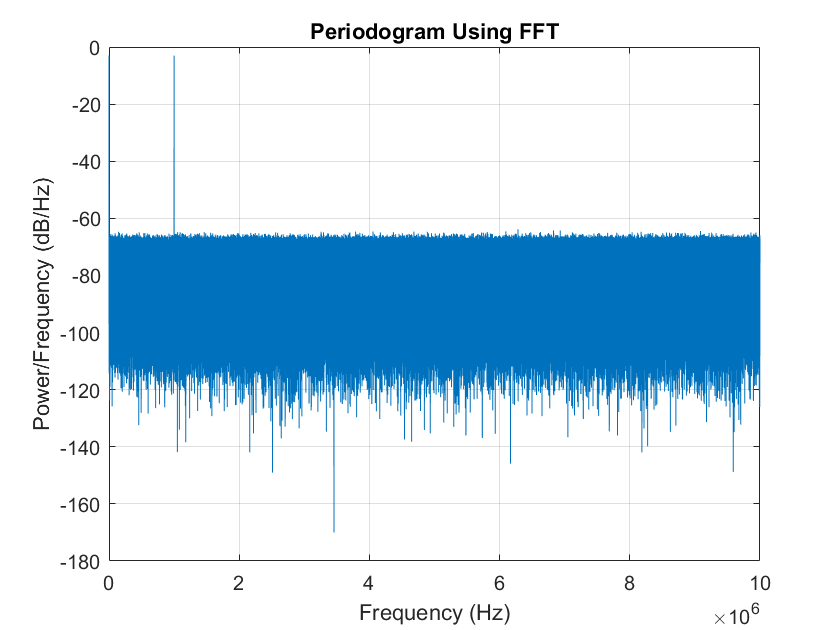


%%%%%%%%
N = length(x);
xdft = fft(x);
xdft = xdft(1:N/2+1);
psdx = (1/(Fs*N)) * abs(xdft).^2;
psdx(2:end-1) = 2*psdx(2:end-1);
freq = 0:Fs/length(x):Fs/2;

plot(freq,10*log10(psdx))
grid on
title('Periodogram Using FFT')
xlabel('Frequency (Hz)')
ylabel('Power/Frequency (dB/Hz)')